# Overlay of Bode diagrams with simple asymptotic information

A file to plot simple asymptotes of the bode plot for systems with only LHP real roots. Asymptotes help students do very rapid sketches of Bode diagrams which aid with developing insight that can be useful in design.

In order to enable rapid sketching, the gain asymptotes use slope information only and the phase asymptotes shift in multiples of 90 degrees. The intention is to gain a rapid overview rather than a moderately precise plot given it is quick and easy to obtain precise plots using computers.

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- What are asymptotes?

- Lead and lag compensation

- Define system, poles and zeros

- Below is the subfunction doing all the computation

## 1. What are asymptotes?

For a simple factor $G\left(s\right)=s+a,$ it is possible to sketch the bode diagram quickly using asymptotic information, that is, what happens when the frequency is small or large?


$$w\gg a\;\Rightarrow \textrm{jw}+a\approx \textrm{jw}\;\;\;\Rightarrow \;\textrm{GAIN}=20\log_{10} w,\;\;\textrm{PHASE}=90$$



$$w\ll a\;\Rightarrow \textrm{jw}+a\approx a$$

$$\;\;\;\Rightarrow \;\textrm{GAIN}=20\log_{10} a,\;\;\textrm{PHASE}=0$$


Hence, the gain is either constant (at $a$), or $\mathrm{w}$, which means a slope in the Bode gain plot of plus/minus 20 dB/dec for zero/pole factors respectively. The phase is zero or 90 degrees, with a value of 45 degrees when $w=a\ldotp$

**NOTE**: Classic approaches would also note that when $w=a,\left|\textrm{jw}+a\right|=a\sqrt{2}$ and the phase is 45 degrees. However, for a very quick sketch, adding such corrections is rarely worth the effort, albeit it is useful insight on how the phase changes. 

A simple example below illustrates the asymptotes for a simple pole factor where the corner frequency in the gain plot at $w=2$is evident and the change in slope of 0 to -20dB/dec. The phase asymptote switches from 0 to -90 degrees, with a value of -45 degrees at the corner frequency. The true Bode diagrams are overlaid so a comparison can be performed.

disp('SECTION WITH SINGLE POLE EXAMPLE')

SECTION WITH SINGLE POLE EXAMPLE


G=tf([1],[1 2])

G =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.



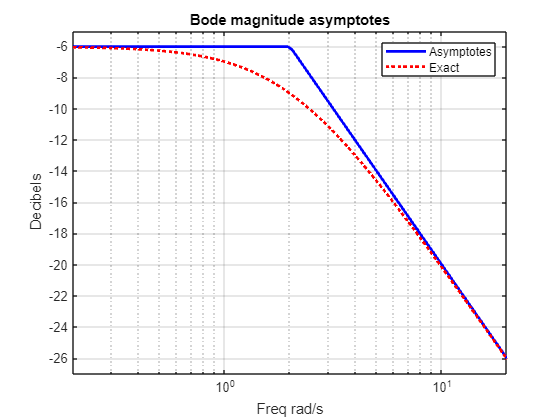

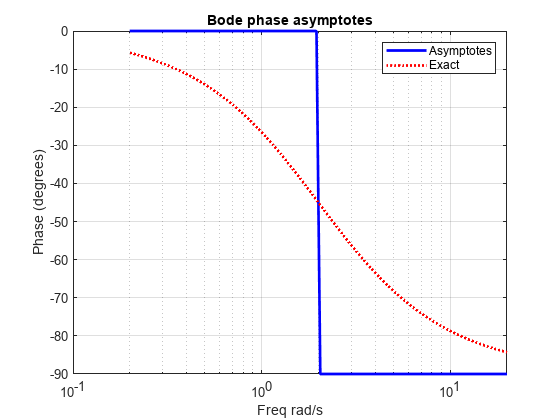

bodeasymptote(G)

## 2. Lead and lag compensation

The asymptotes of a lead and lag are particular useful as these are used in design. This section simply produces the asymptotes for a lag (change numbers below for a lead) so students can see the core attributes.

disp('SECTION WITH LAG COMPENSATOR EXAMPLE')

SECTION WITH LAG COMPENSATOR EXAMPLE


G=4*tf([1 8],[1 2])

G =
 
  4 s + 32
  --------
   s + 2
 
Continuous-time transfer function.



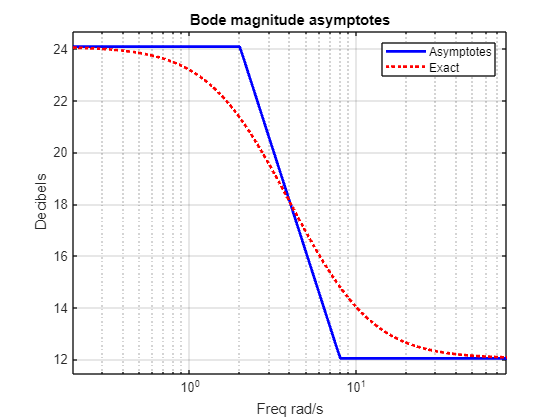

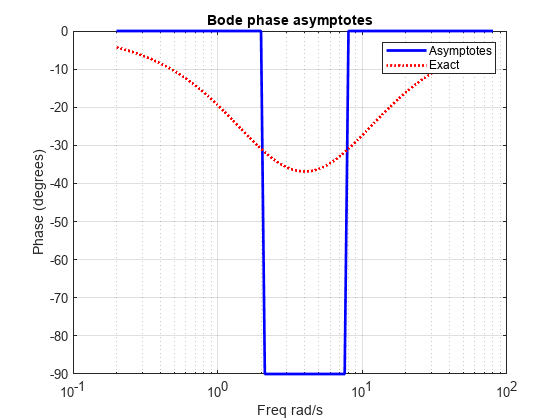

bodeasymptote(G)

## 3. Define system, poles and zeros

This file is to aid learning and thus not intended to be comprehensive. It works only with real LHP poles and zeros. Extensions to RHP and complex poles/zeros require insight and manipulation that is not merited in such a simple illustration.

One can enter the transfer function directly below as a transfer function or by giving poles/zeros and a gain.

disp('SECTION WITH MORE COMPLICATED EXAMPLE')

SECTION WITH MORE COMPLICATED EXAMPLE


gain = 10;
poles = [0 -1 -4 -10];
zeros = [-2];
G=gain*tf(poly(zeros),poly(poles));

The subfunction below is used to do all the computation and is not commented in fine detail as the coding is rather fussy and not particularly interesting.

G

G =
 
           10 s + 20
  ----------------------------
  s^4 + 15 s^3 + 54 s^2 + 40 s
 
Continuous-time transfer function.



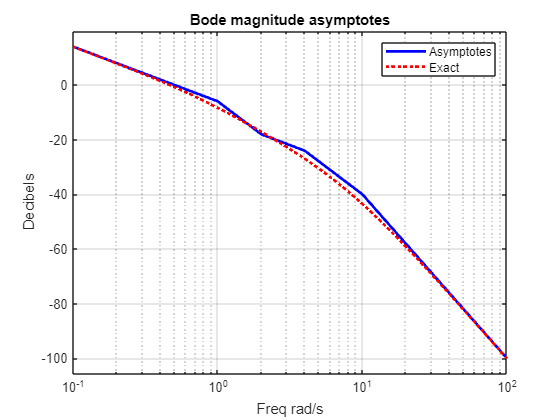

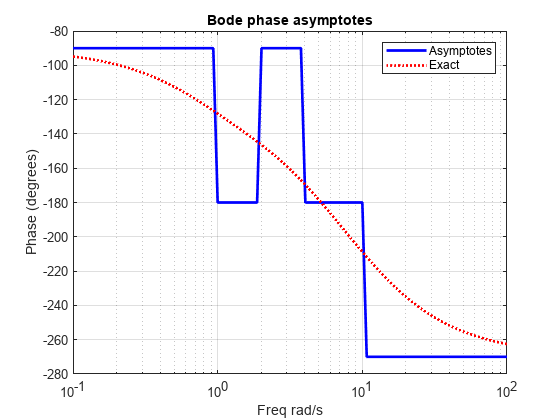

bodeasymptote(G)

## 4. Below is the subfunction doing all the computation

There is no particular need to read this unless interested.

function bodeasymptote(G)


%%%%%% Compute poles and zeros and first coefficient of n(s)
[n,d] = tfdata(G,'v');  
z=real(roots(n)); 
p = real(roots(d));
gain=n(end)/(d(1)*prod(z)*(-1)^length(z));
if gain<0
    ph0=180;
  else ph0=0;
end
if max(imag(p))==0
    if length(z)<1|max(imag(z))==0

%%%% Sort poles/zeros into order
[pp,pos] = sort(abs(p));
p=p(pos);
[zz,pos2] = sort(abs(z));
z=z(pos2);

%%%% Decide on frequency list
keep = [zz;pp]>0;
zzpp=[zz;pp];

wmin = min(zzpp(keep))/10;
wmax = max([zz;pp])*10;
w=logspace(log10(wmin),log10(wmax),100);
[mag,phase] = bode(G,w);


%%%%%% Calculate bode values for each pole factor (s+a) independently
g=[];
for k=1:length(p)
    for kk=1:length(w)
        if w(kk)<abs(p(k))&p(k)~=0
            g(k,kk)=1/-p(k);
            ph(k,kk)=0;
        else
            g(k,kk)=1/w(kk);
            ph(k,kk)=-90;
        end
    end
end


%%%%%% Calculate bode values for each zero factor (s+a) independently
gg=[];phh=[];
for k=1:length(z)
    for kk=1:length(w)
        if w(kk)<abs(z(k))
            gg(k,kk)=-z(k);
            phh(k,kk)=0;
        else
            gg(k,kk)=w(kk);
            phh(k,kk)=90;
        end
    end
end


%%%% Add all factors together
G=20*log10([g;gg]);
G=20*log10(abs(gain))+sum(G,1);
PH = sum([ph;phh],1)+ph0;
diffG=max(G)-min(G);


%%% Plot results
figure;clf 
 semilogx(w,G,'b-',w,20*log10(mag(:)),'r:','linewidth',2);
grid
xlabel('Freq rad/s');
ylabel('Decibels');
title('Bode magnitude asymptotes');
axis([wmin,wmax,(min(G)-diffG/20),(max(G)+diffG/20)]);
legend('Asymptotes','Exact');

figure;clf ;
semilogx(w,PH,'b-',w,phase(:),'r:','linewidth',2);
xlabel('Freq rad/s');
ylabel('Phase (degrees)');
title('Bode phase asymptotes');
legend('Asymptotes','Exact');


grid

end;end

end